mass = 0.1; %kg
radius = 0.03; %m

oc_mass = 0.05; %kg
oc_pos = [0 ; 0.01]; %m
com = oc_mass * oc_pos;

I = (0.5 * mass * radius^2) + (oc_mass * norm(oc_pos)^2)

I = 5.0000e-05

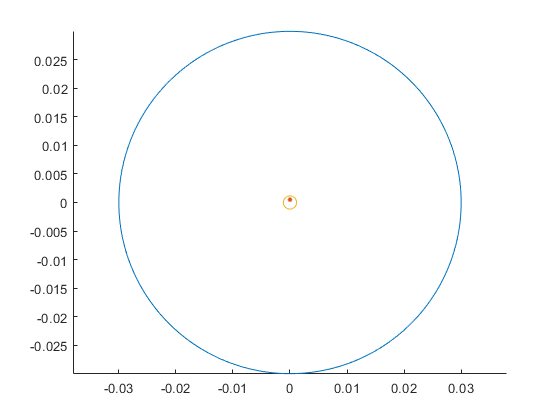


plot_disk(radius, com)


angular_velocity = 1000 * 2*pi / 60;
angular_acceleration = 0;

dt = 0.001;
t_range = 0:dt:0.1;
torque = 0;
theta = 0;
com_pos = [];
data = [];
force = [];



for t = t_range
    torque = norm(com) * 9.8 * (oc_mass + mass) * sin(theta);
    
    angular_acceleration = torque / I;
    
    angular_velocity = angular_velocity + dt * angular_acceleration;
    
    theta = theta + (dt * angular_velocity) + (0.5 * dt * angular_acceleration^2);
    
    
    
    com_pos(:,end+1) = [norm(com) * cos(theta) ; norm(com) * sin(theta)];
    
    data(:,end+1) = [torque; angular_velocity; angular_acceleration];
    force(:,end+1) = (mass + oc_mass) * (angular_velocity / radius)^2 / norm(r);
    
end

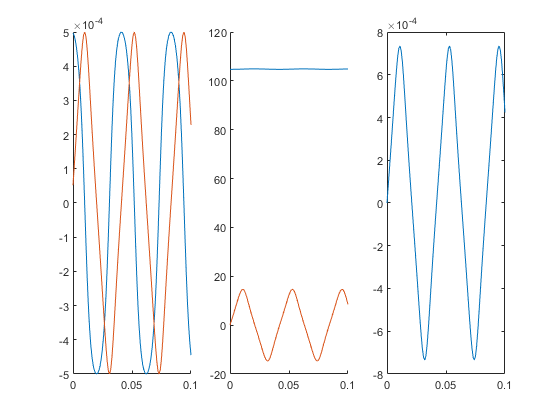


figure()
clf

subplot(2,2,1)
hold on
plot(t_range, com_pos(1,:))
plot(t_range, com_pos(2,:))
hold off

subplot(2,2,2)
hold on
plot(t_range, data(2,:))
plot(t_range, data(3,:))
hold off
subplot(2,2,3)



plot(t_range, data(1,:))


subplot(2,2,4)
plot(t_range, force)





